clear 
close all
clc

% Define the base directory for input and output files
input_dir = 'D:\Matlab\Matlab input\20240715_full_plate\20240715_nonrot_2.6Hz_7mm_full_plate_separate_frames\Results\';
output_dir = 'D:\Matlab\Matlab output\20240715_full_plate_results\20240715_nonrot_2.6Hz_7mm_full_plate\';

% Define the base file name and extension
base_file_name = '20240715_nonrot_2.6Hz_7mm_full_plate_frame_';
file_extension = 'A_vel_new.dat';

% Define the range of frames to process
start_frame = 160;
end_frame = 164;
nt = end_frame - start_frame;

% Load one file to get the dimensions
file_name = [base_file_name, '0220', file_extension];
input_file = fullfile(input_dir, file_name);
dr = loadvec(input_file);
% Copy dr to dr_new & delete rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new, h_0);

[nx, ny] = size(h.w);

surface_height = zeros(nx, ny, nt);

for frame_num = start_frame:end_frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);
    
    % Load the data
    dr = loadvec(input_file);
    % Copy dr to dr_new & delete rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
    h = surfheight(dr_new, h_0);

    % Store the 2D matrix in the 3D matrix
    surface_height(:,:,frame_num-start_frame+1) = h.w;
end

% matrix = surface_height(30,40,:)
% plot(matrix)


% Surface height on short axis
% Plot the amplitude/surface height over the short axis
%ampl = surface_height(30,:,2);
ampl = surface_height(:,40,2);
%ampl = surface_height(30,40,:);
%values_short_axis = h.y;
values_long_axis = h.x;
%values_time_axis = start_frame:1:end_frame;
%plot(values_short_axis,ampl)
plot(values_long_axis,ampl)
%plot(values_time_axis,ampl)
title('Amplitude')
xlabel('Position on short axis')
ylabel('Amplitude')

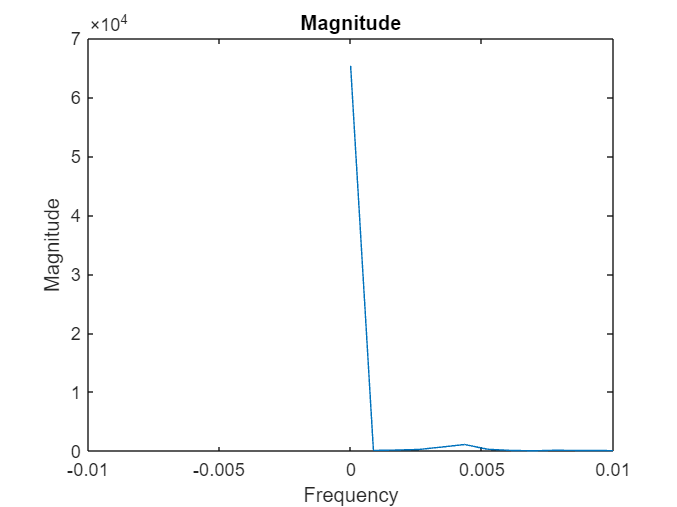


% Compute Fourier transform and rewrite frequency
four = fft(ampl);
%distance = h.y(2)-h.y(1);
distance = h.x(2)-h.x(1);
%distance = 1;
freq = 1/distance;
freq_four = (0:length(four)-1)*freq/length(four);

% Plot the Fourier transform against frequencies
plot(freq_four,abs(four))
xlabel('Frequency')
ylabel('Magnitude')
title('Magnitude')
xlim([-0.01 0.01]);

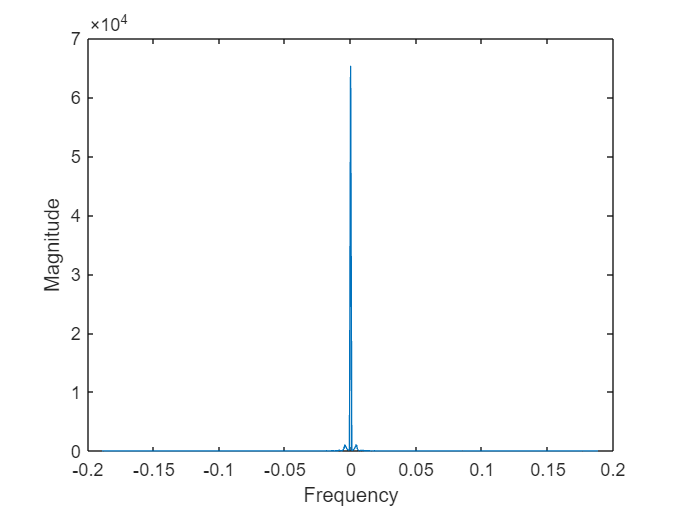


% Shift Fourier transform to be symmetric around 0.
n = length(ampl);
freq_shift = (-n/2:n/2-1)*(freq/n);
four_shift = fftshift(four);
plot(freq_shift,abs(four_shift))
xlabel('Frequency')
ylabel('Magnitude')

% Tryout example
% Create and plot a signal x
Ts = 1/50;
t = 0:Ts:10-Ts;
x = sin(2*pi*15*t) + sin(2*pi*20*t);
plot(t,x)
xlabel('Time (seconds)')
ylabel('Amplitude')


% Compute Fourier transform of x and formulate frequency f
y = fft(x);
fs = 1/Ts;
f = (0:length(y)-1)*fs/length(y);

% Plot Fourier transform as function of frequency
plot(f,abs(y))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')


% Shift Fourier transform to be symmetric around 0
n = length(x);
fshift = (-n/2:n/2-1)*(fs/n);
yshift = fftshift(y);
plot(fshift,abs(yshift))
xlabel('Frequency (Hz)')
ylabel('Magnitude')

% % Perform 3D Fourier Transform
% H = fftn(surface_height);
% 
% % Calculate the magnitude
% magnitude = abs(H);
% 
% % Define the frequency axes
% [Nx, Ny, Nt] = size(H);
% fx = linspace(-Nx/2, Nx/2-1, Nx); % Spatial frequencies in x direction
% fy = linspace(-Ny/2, Ny/2-1, Ny); % Spatial frequencies in y direction
% ft = linspace(-Nt/2, Nt/2-1, Nt); % Temporal frequencies
% 
% % Shift the zero frequency component to the center of the spectrum
% magnitude_shifted = fftshift(magnitude);
% 
% % 3D surface plot for a specific temporal frequency slice
% timeIndex = round(Nt / 2); % Mid-point in the temporal frequency domain
% [X, Y] = meshgrid(fx, fy);
% figure;
% surf(transpose(X), transpose(Y), magnitude_shifted(:, :, timeIndex));
% title(['Magnitude of Fourier Transform at temporal frequency index ', num2str(timeIndex)]);
% xlabel('Spatial frequency in x direction');
% ylabel('Spatial frequency in y direction');
% zlabel('Magnitude');
